fun = @(x) 0.2*x+0.4*sin(10*x)+(0.1*x.^2-0.4).^2;
g1 = @(x) x.^3 - 4.4*x.^2+1.64*x-0.16;
g2 = @(x) -x.^3+8.2*x.^2-17.6*x+3.2;
g3 = @(x) x.^2 - 4.2*x + 0.8 %opcjonalne ograniczenie

g3 = function_handle with value:
    @(x)x.^2-4.2*x+0.8


gi = {g3};
[x0, functions] = kara_zew(fun, -4, gi, 0.5, 0.001, 100);

Liczba iteracji: 4



disp("Przybliżone minimum = " + num2str(x0))

Przybliżone minimum = 0.46853


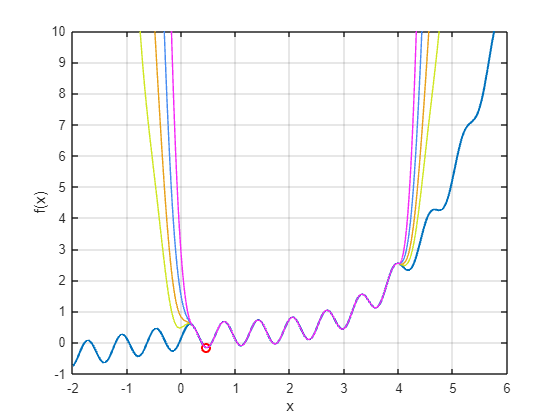


figure
fplot(fun, [-2, 6], "linewidth", 1.5)
hold on
plot(x0, fun(x0), 'ro', "linewidth", 1.5)
xlabel("x")
ylabel('f(x)')
grid on
% Elementy kosmetyczne, niekoniecznie potrzebne
ylim([-1, 10])
for func = functions
    col = [randi([1 99]), randi([1 99]), randi([1 99])]/100;
    fplot(func, [-2, 6], 'color', col);
end

g1 = @(x) x.^2 + 1.7*x;
%g2 = @(x) x.^3+3.4*x.^2+2.89*x;
gi = {g1};
[x0, functions] = kara_wew(fun, -0.6, gi, 0.5 ,0.5, 0.001, 100);

Liczba iteracji: 4


disp("Przybliżone minimum = " + num2str(x0))

Przybliżone minimum = -0.79481


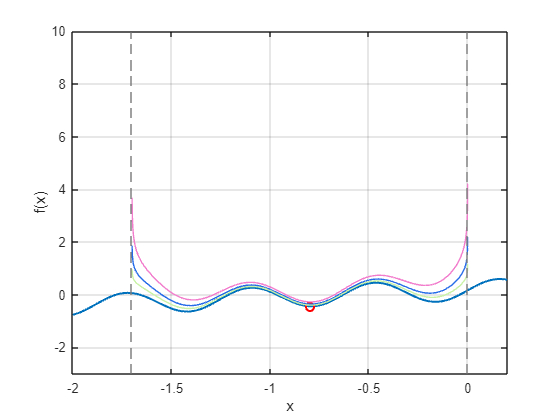

figure
fplot(fun, [-4, 4], "linewidth", 1.5)
hold on
plot(x0, fun(x0), 'ro', "linewidth", 1.5)
xlabel("x")
ylabel('f(x)')
grid on
% Elementy kosmetyczne, niekoniecznie potrzebne
ylim([-3, 10])
xlim([-2, 0.2])
for func = functions
    col = [randi([1 99]), randi([1 99]), randi([1 99])]/100;
    fplot(func, [-2, 6], 'color', col);
end

function [out, F_vec] = kara_wew(fun, x0, gi, c0, alpha, eps, n_max)
    options = optimset('MaxIter', 5, 'Display', 'off');
    i = 0;
    x_prev = x0;
    c = c0;
    S = @(x) 0;
    F_vec = {};
    for i = 1:length(gi)
        g = gi{i};
        S = @(x) S(x) - log(-g(x));
    end
    while true
        i = i + 1;
        F = @(x) fun(x) + c.*S(x);
        F_vec{end + 1} = F;
        x = fminsearch(F, x_prev, options);
        if abs(x-x_prev) < eps || c*abs(S(x)) < eps || i >= n_max
            disp("Liczba iteracji: " + num2str(i))
            out = x;
            return 
        end
        c = alpha*c;
        x_prev = x;
    end
end


function [out, F_vec] = kara_zew(fun, x0, gi, c0, eps, n_max) 
    options = optimset('MaxIter', 5, 'Display', 'off');
    i = 0;
    x_prev = x0;
    c = c0;
    S = @(x) 0;
    F_vec = {};
    for j = 1:length(gi)
        g = gi{j};
        S = @(x) S(x) + (max(0, g(x))).^2;
    end
    while true
        i = i + 1;
        F = @(x) fun(x) + c*S(x);
        F_vec{end + 1} = F;
        x = fminsearch(F, x_prev, options);
        if abs(x-x_prev) < eps || i > n_max
            disp("Liczba iteracji: " + num2str(i))
            out = x;
            return 
        end
        c = 2*c;
        x_prev = x;
    end
end